a = zeros(1,10);
a(4:6) = 1;
plot(a)

hold on;

kernel = [1 1 1];
aflit = a; 

for i = 2:9
aflit(i) = sum(a(i-1 : i+1).*kernel);
end

plot(aflit) % Cross flitering, showing frequency of 1's
% this gives us values greater than 1, which we don't want
% so we take weighted average of kernel 

kernel = kernel / sum(kernel);
aflit = a;
for i = 2:9
aflit(i) = sum(a(i-1 : i+1).*kernel);
end
plot(aflit)
% This is called a cross correlation
% But we will use convolution 

Convolution is very easy to work with as it is associative and additive, and keeps scale of image 

Now let's focus on gaussian fliter 

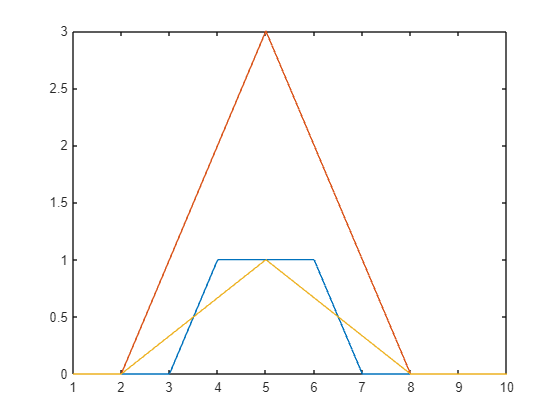

hold off;

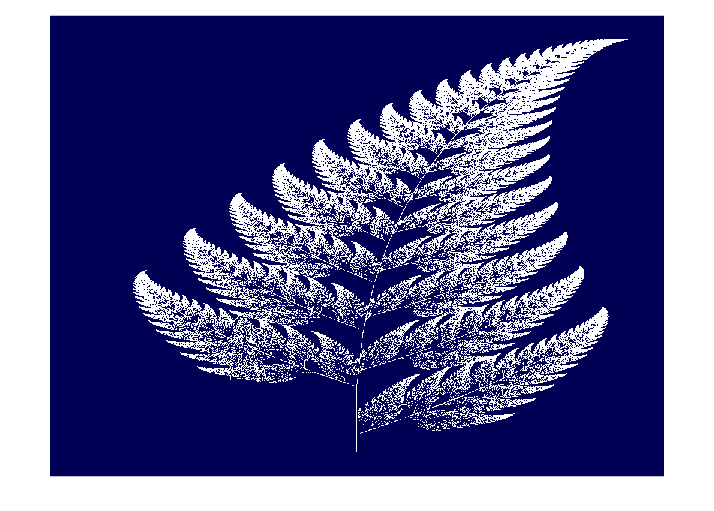

image = imread('fern.png');
image = im2double(image);
imshow(image)


boxkern = ones(25)

boxkern =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1

boxkern = boxkern/sum(boxkern(:))

boxkern =     0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0

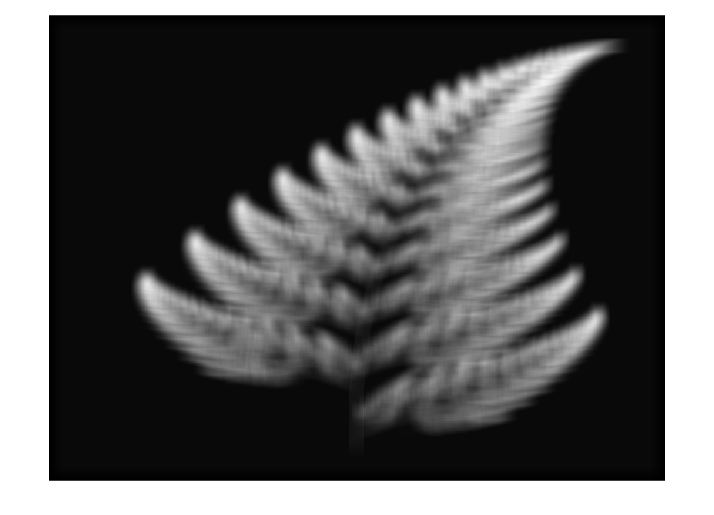

imshow(conv2(rgb2gray(image),boxkern)); % Convert to gray as

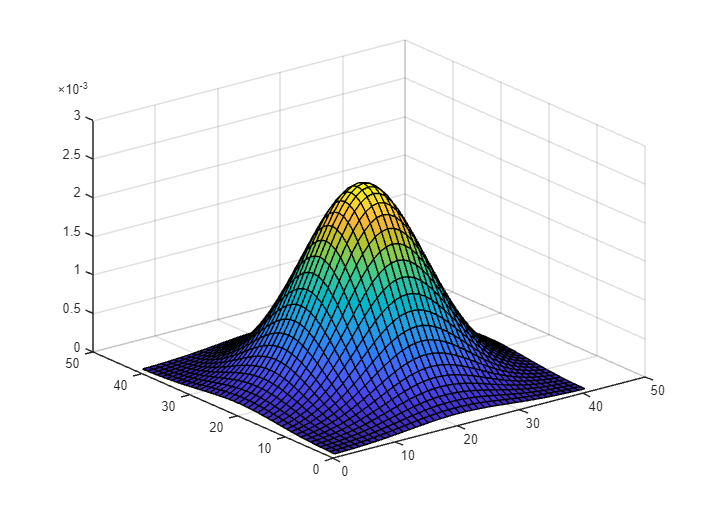

% convolution function only takes in 2D, not 3D
% box filtering

% now do it with a color image 
gauskern = fspecial('gaussian', 41, 8); 
% gaussian fliter, with 41x41 dimension and SD 8
% we choose odd numbers for the dimensions as the size of pixels 
% are discrete so if we want to center one kernel on top of a pixel 
% it needs to be odd

surf(gauskern) % Visual of kernel 

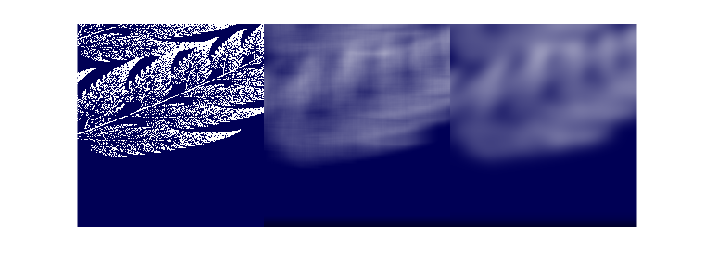

% Gaussian distribution is normal distribution 

% Now let's fliter our image with gauss & box kern 
imgaus = imfilter(image,gauskern);
imbox = imfilter(image, boxkern);
imshow([image(550:end, 600:800, :) imbox(550:end, 600:800, :) imgaus(550:end, 600:800, :)])

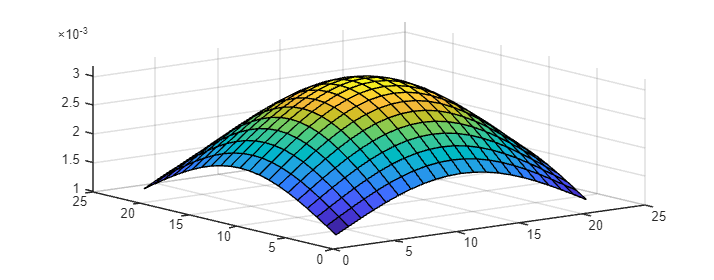

% both images are blurred, but guassian blur looks more natural, while box
% kernel has sharp edges 

surf(fspecial('gaussian', 21, 10)) 

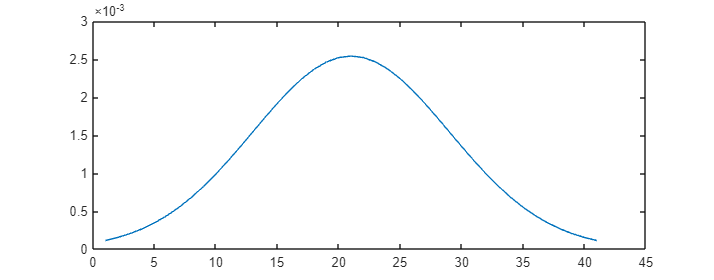

% The kernel ends before the gaussian becomes 0 in all directions
% this is bad as the kernel's dimensions won't represent the whole image 

gaus1d = gauskern(21, :);
plot(gaus1d); % 1 dimension kernel 

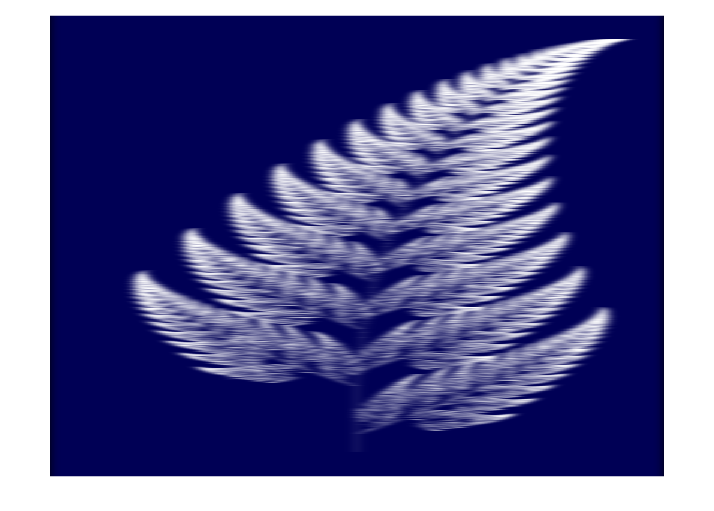

gaus1d = gaus1d/sum(gaus1d);
imshow(imfilter(image, gaus1d)) % this is filtered only in x direction

filtx = imfilter(image, gaus1d);

% gaus1d is only indexed by columns, so it's one row vector, which is why
% it's flitered in x direction 
% to make it filter in y direction, use transpose
filty = imfilter(image, gaus1d');
imshow(filty)

% now let's use both directions 
filtxy = imfilter(imfilter(image, gaus1d), gaus1d'); % this is the same as our gaussian filter 
imshow(filtxy)

that is gaussian flitering, a natural way to blur images 

kern = zeros(41);
kern(2,2) = 1;
imshow(kern)

filtered = imfilter(image, kern);
filcrop = filtered(550:end, 600:800, :);
imagecrop = image(550:end, 600:800, :);
imshow([imagecrop filcrop])
% the images is shifted 

% we can see this more clearly overlaying the two pictures on each other
% and using alpha 
imshow(0.5*imagecrop + 0.5*filcrop)

One useful application of flitering is denoising 

gaus2 = fspecial('gaussian', 5, 1);
surf(gaus2)
filt2 = imfilter(image, gaus2);
imshow([image(100:150, 450:500, :) filt2(100:150, 450:500, :)])

% We can also sharpen images 

imshow(imgaus)
imshow(2*abs(image - imgaus))
% This will highlight edges, which was blurred by gaussian filter
sharp = image + (image - imgaus);
imshow(sharp)
imshow([image(:, 200:800, :), sharp(:, 200:800, :)])

Up until now, we have done linear filtering where all the filtered pixels are linear combinations of original image

now let's do non linear filtering 

% First up is median filtering 
% Median finds "middle" value of data set, what median filtering does is
% give you middle value of picture. This is not linear as you can't
% multiply or add filter and get same result in end 
% median filter in matlab only allows single channel image
gray = rgb2gray(image);
imshow(gray)
imshow(medfilt2(gray, [15 15]))

% A good use of median filtering is to get rid of salt and pepper noise. 
% Make artificial noise
noi = imnoise(gray, 'salt & pepper');
imshow(noi); % will add completely black/white pixels 
% mean filtering will not work as the 0/1 values will shift all other
% pixels. In constrant median of image will not be affected as it's the
% middle values, not beginning/end (0/1)
imshow(medfilt2(noi, [7 7]))

We are defining the fliter for a specific pixel by it's neighbours 

labim = rgb2lab(image);
imshow(labim(:, :, 1)/100)
imshow(labim(:,:,3))
binaryimage = labim(:,:,3) < -25; % does per pixel comparison
imshow(binaryimage)